**READ ME**

- This code is only made for the case in problem 4 only and solves using 

            i.   general polynomial basis function : 1 + x + x^2 + x^3 + ..... + x^N.

            ii.  hierarchical polynomials basis functions. 

            iii. linear finite element basis functions.

- When asked for type of basis function :

            - Enter "1" :  for general polynomial.

            - Enter "2" : hierarchical polynomials.

            - Enter "3" : linear finite elements.

- k can be 0 or any other number.

- axial force distribution can be a number or a function of x.

- **Number of elements must be odd.**

Clear all stored variables and commands

clear all
clc

Define basic settings

format long
syms x

Getting the basic inputs

EA = input('EA = ')

EA =      1


k = input('spring constant assosciated with the member, k = ')

k =     10


L = input('Length of Bar = ')

L =      1


f = input('Distribution (use small letter "x" if it is a variable) of axial force = ')

$$f = 10\,x$$

Boundary condition at x = 0

U_0 = input('Give the displacement at the end x = 0 :  ')

U_0 =      0


Boundary condition at x = L and L/2

P_L = input('Give the force at the end x = L :  ')

P_L =     10


Po = input('Force at L/2 :  ')

Po =      5


Type of basis

T = input('Enter the type of basis :  ')

T =      3


if T == 1
    N = input('Enter the order of the polynomial :  ')+1

Initializing

    Phi = sym(zeros(N,1));
    K = zeros(N);
    F = zeros(N,1);

Establishing the Basis functions

    for i = 1:N
        Phi(i) = x^(i-1);
    end
    dPhi = diff(Phi);
    Phi
    dPhi

Calculating the Stiffness Matrix  and the Force vector

    for i = 1:N
        for j = 1:N
            K(i,j) = int(EA*dPhi(i)*dPhi(j)+k*Phi(i)*Phi(j),x,0,L);
        end
        F(i,1) = int(f*Phi(i),x,0,L) + subs(P_L*Phi(i),x,L) + subs(Po*Phi(i),x,L/2);
    end
    K
    F

Computing the Solution

    K(1,:) = 0;
    F(1) = 0;
    K(:,1) = 0;
    K(1,1) = 1;


    Alpha = K\F;
    U = vpa(Alpha'*Phi)

Plotting 

    t = linspace(0,L,100);
    u = subs(U,x,t);
    figure()
    plot(t,u,'r','Linewidth',0.2)

elseif T == 2
    N = input('Enter the order of polynomial :  ')+1

Initializing

Phi = sym(zeros(N,1));
K = zeros(N);
F = zeros(N,1);

Establishing the Basis functions

Phi(1) = 1-(x/L);
Phi(2) = x/L;
if N>2
    Phi(3) = x*(L-x);
    if N>3
        for i = 4:N
            Phi(i) = Phi(3);
            for j = 1:i-3
                Phi(i) = Phi(i)*(((j)*(L/(i-2)))-x);
            end
        end
    end
end
for i = 3:N
    Phi(i-1) = Phi(i);
end
Phi(end) = x;
dPhi = diff(Phi);
Phi

nel =      5


Calculating the Stiffness Matrix  and the Force vector

for i = 1:N
    for j = 1:N
        K(i,j) = int(EA*dPhi(i)*dPhi(j)+k*Phi(i)*Phi(j),x,0,L);
    end
    F(i,1) = int(f*Phi(i),x,0,L) + subs(P_L*Phi(i),x,L) + subs(Po*Phi(i),x,L/2);
end

K
F

Computing the Solution

K(1,:) = 0;
F(1) = 0;
K(:,1) = 0;
K(1,1) = 1;


Alpha = K\F;
U = vpa(Alpha'*Phi)

Plotting 

t = linspace(0,L,100);
u = subs(U,x,t);
figure()
plot(t,u,'r','Linewidth',0.2)


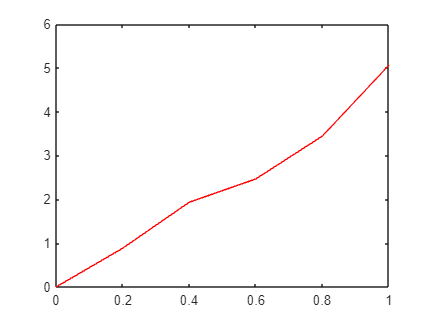

else
    nel = input('Enter the number of elements: ')   
    x_0 = 0 ;
    x_L = L;

    K = zeros(nel+1,nel+1);
    F = zeros(nel+1,1);


    h = (x_L - x_0)/nel;

    x1 = 0:h:(x_L-h);
    x2 = h:h:x_L;



    for e = 1:nel

        FF = zeros(2,1);
        KK = zeros(2);

        X1 = x1(e);
        X2 = x2(e);

        N1 = (X2 - x)/h;
        N2 = (x - X1)/h;

        N = [N1,N2];
        dN = diff(N);

        for i = 1:2
            FF(i) = FF(i) + int(f*N(i),X1,X2);
            for j = 1:2
                KK(i,j) = KK(i,j) + int(EA*dN(i)*dN(j) + k*N(1)*N(2),X1,X2);
            end
        end
        for i = 1:2
            ig = e + (i-1);
            F(ig) = F(ig) + FF(i);
            for j = 1:2
                jg = e + (j-1);
                K(ig,jg) = K(ig,jg) + KK(i,j);
            end
        end
    end
    
    F(end) = F(end) + P_L;
    F((nel+1)/2) = Po;
        K(1,:) = 0;
        K(:,1) = 0;
        K(1,1) = 1;
        F(1) = 0;
       

    Alpha = K\F;

    for i = 1:nel

        X1 = x1(i);
        X2 = x2(i);

        N1 = (X2 - x)/h;
        N2 = (x - X1)/h;

        U(i) = Alpha(i)*N1 + Alpha(i+1)*N2;
    end


Plotting 

    figure();
    for i = 1:nel
        t = linspace(x1(i),x2(i),20);
        u = subs(U(i),x,t);
        plot(t,u,'r','Linewidth',0.2);
        hold on
    end

end
hold off 
